# **Robot Animation, Isometric GIF and Planar Views**

**Test Case With UR5 Robot**

being developed for any n jointed architecture

By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Ohio State University | 11/13/2022

with use of Modern Robotics by Kevin M. Lynch and Frank C. Park

### Summary

%%
% By Brian Joseph Lesko
% 
% Revised by:
% Date:
%
% Input 
%     joint position list  N steps of time by n joints
%     time information for each step of N  
%     Mlist: List of link frames i relative to i-1 at the home position,
%     Slist: Screw axes Si of the joints in a space frame, in the format
% Output 
%     3D Gif animation
%     Preview of start and ending positions
%%

Clearing 

clc; clear; close all;

### Loading the test data

thetamat = getUR5thetamat();
traj = thetamat;
totalTime = 3; %Seconds
integrations_per_second = 100;
%Integration 
intRes = 10;
N = totalTime*integrations_per_second/intRes; %number of steps
dt = 1/N; %time step
time = linspace(0,totalTime,N)';
[Glist,Mlist,Slist] = getUR5();

### Output Settings

Matlab Camera Angles 

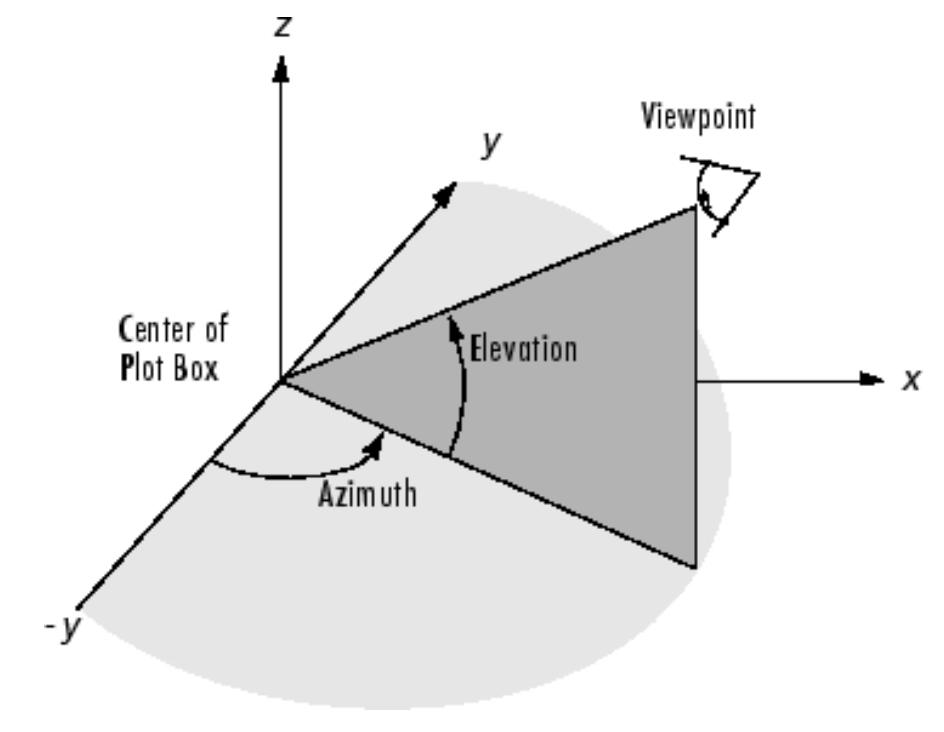

Azimuth and Elevation angles describe the camera projection in MATLAB

%Input Viewing Angle
Isometric = [-45 35.264]; xyPlane = [90 90]; xzPlane = [0 0]; yzPlane = [90 0];
viewAngle = Isometric;

%Saving To
filename = 'animation.gif';

%Color Pallete 
figure; hold on
joint_num = length(traj(1,:));
background = "#F6F6F3"; set(gca,'Color',background); linkColor = '#BA2D0B';
colorBank = ["#553739","#273C2C","#260C03","#588B8B","#723A08","#2A3D45","#47682C","#33658A","#FF7F51","#929487","#A1B0AB","#C3DAC3","#F5D491","#621708","#DB9065","#48BEFF"];
cmap = colorBank(randperm(length(colorBank),joint_num)); %Random organization 

### Calculating 

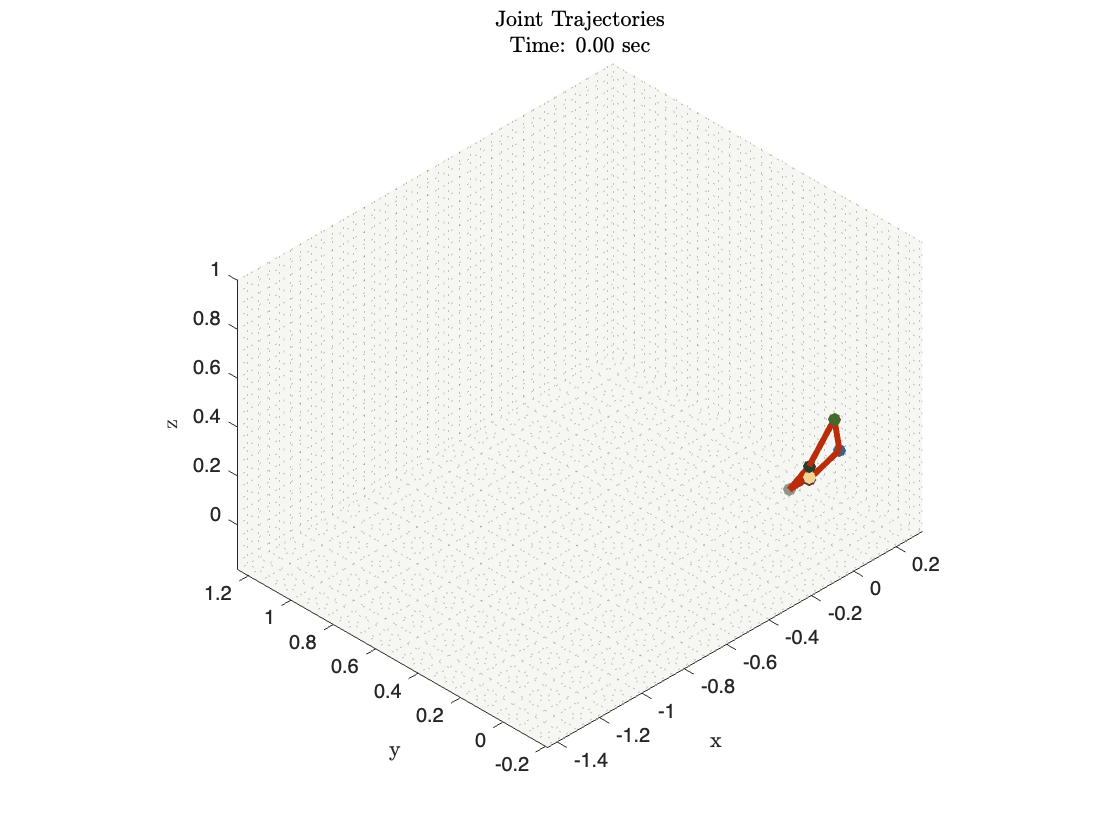

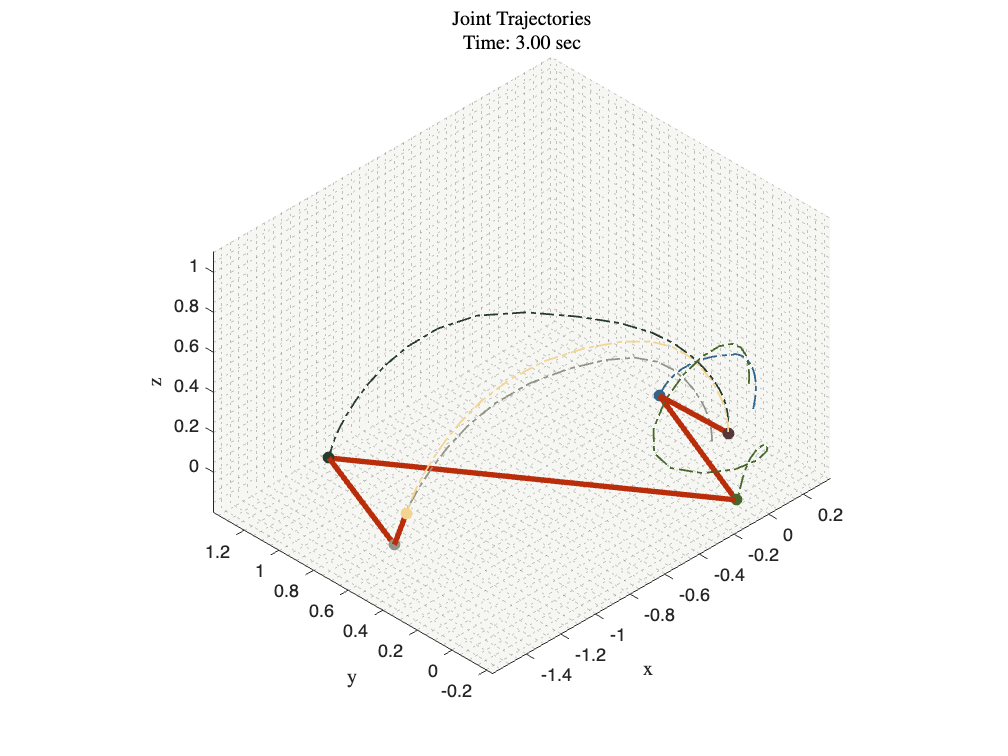

%initialize axis limits
axisLimits.xmin=-0.01; axisLimits.xmax=0; axisLimits.ymin=-0.01; axisLimits.ymax=0; axisLimits.zmin=-0.01; axisLimits.zmax=0;

for loop = 1:1:2 
    %The outter for loop causes the calculations for joint positions to happen twice
    %The first pass is for setting axis limits and the second will animate

    %Initializing joint and link histories 
    p_history = zeros(length(time),3,joint_num); %joint history
    link_history = zeros(length(time),3,3,joint_num-1); %4D vector for link history

for t = 1:1:length(time)

    if loop == 2
    clf 
    holdPlotSettings(axisLimits,background,viewAngle,time(t)); hold on
    end 
    
    %Theta current
    theta_now = traj(t,:)';
    %CALCULATING THE POSITION OF JOINT N AT TIME T
    M = eye(4); %Initialize M
    for n = 1:1:joint_num

        [p_now,p_history] = customForwardKinematics(M,Mlist,Slist,n,t,theta_now,p_history);

        %check limits
        if loop == 1 %Loop 1 is for checking the axis limits
        [axisLimits] = checkAxisLimits(p_now,axisLimits); end 

        %Plotting the Joints, Links, and joint paths
        if loop == 2
            link_history = plotLinks(p_now,p_history,n,t,link_history,linkColor);
            plotJoints(p_now,cmap,n)
            plotJointPaths(p_history,cmap,n,t)
        end 
    end %end of joints

    if loop == 2
        holdPlotSettings(axisLimits,background,viewAngle,time(t)); hold on, grid minor
        saveFrame(filename,t);
    end 

end 
increase = 1.1;
axisLimits = increaseAxisLimits(axisLimits,increase); hold on
holdPlotSettings(axisLimits,background,viewAngle,time(t)); grid minor, hold on %Previous of final Position
end 

# Functions

Plot Links 

function link_history = plotLinks(p_now,p_history,n,t,link_history,linkColor)
%Calculate Link Path, given joint history
    %link_n_history = zeros(3,3,n-1); %Initialize
    if n>1 
        link_now = zeros(3,3); %initialized
        for g = 1:1:3
            link_now(:,g) = linspace(p_now(g),p_history(t,g,n-1),3);
        end
        %link_n_history(:,:,n-1) = link_now; %Works but unused
        link_history(t,:,:,n-1) = link_now;
%Plot    
        plot3(link_now(:,1),link_now(:,2),link_now(:,3),'Color',linkColor,'LineWidth',3);
    end %end of links
end 

Plot Joints and Paths

function plotJoints(p_now,cmap,n)
    scatter3(p_now(1),p_now(2),p_now(3),'MarkerEdgeColor',hex2rgb(cmap(:,n)),'MarkerFaceColor',hex2rgb(cmap(:,n)));
end 
function plotJointPaths(p_history,cmap,n,t)
    plot3(p_history(1:t,1,n),p_history(1:t,2,n),p_history(1:t,3,n),"-.",'Color',cmap(:,n),'LineWidth',1); 
end 

during loop 1, Joint locations are used to set axis limits for loop 2

function [axisLimits] = checkAxisLimits(p_now,axisLimits)
x = p_now(1); y = p_now(2) ; z = p_now(3);
%Check the current point in 3D space
%Goal of the function is to get the maximum and minimum x y z for all time
%For setting axis limits
        if x > axisLimits.xmax
            axisLimits.xmax = x; 
        elseif x < axisLimits.xmin
            axisLimits.xmin = x; 
        end 
        if y > axisLimits.ymax 
            axisLimits.ymax = y; 
        elseif y < axisLimits.ymin
            axisLimits.ymin = y; 
        end 
        if z > axisLimits.zmax
            axisLimits.zmax = z;
        elseif z < axisLimits.zmin
            axisLimits.zmin = z; 
        end 
end 

function [axisLimits] = increaseAxisLimits(axisLimits,inc)
%Simply to shorten the code above
    axisLimits.xmin = inc*axisLimits.xmin; 
    axisLimits.xmax = inc*axisLimits.xmax; 
    axisLimits.ymin = inc*axisLimits.ymin;
    axisLimits.ymax = inc*axisLimits.ymax;
    axisLimits.zmin = inc*axisLimits.zmin;
    axisLimits.zmax = inc*axisLimits.zmax;
end 

Set Axis Limits, label axis, set grid and background color, set view angle

function holdPlotSettings(axisLimits,background,viewAngle,current_time)
    %Brian Lesko
    % Updating the title and axis
    title(sprintf('Joint Trajectories\nTime: %0.2f sec', current_time),...
        'Interpreter','Latex');
    xlabel('x', 'Interpreter', 'Latex'),ylabel('y', 'Interpreter', 'Latex'),zlabel('z', 'Interpreter', 'Latex')
    %updating other plot settings
    grid minor, axis equal, view(viewAngle(1),viewAngle(2));  % Setting view angle
    set(gca,'Color',background)
    %Updating the axis limits
    xl = [axisLimits.xmin axisLimits.xmax]; yl = [axisLimits.ymin axisLimits.ymax]; zl = [axisLimits.zmin axisLimits.zmax];
    xlim(xl); ylim(yl); zlim(zl);
    hold on
end 


To save the animation as a GIF

function saveFrame(filename,t)
%SAVE FRAME
        % delay
        pause(0.005)
        % saving the figure
        frame = getframe(gcf);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if t == 1 %create the file if t is 1
          imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
          %Could write a preprogrammed image here
        end 
        if t > 1 %just append to the file if its not t = 1
        imwrite(imind,cm,filename,'gif','WriteMode','append')%,...
        %'DelayTime',0.1);
        end 
end 

Forward Kinematics Custom Call

function [p_now,p_history] = customForwardKinematics(M,Mlist,Slist,n,t,theta_now,p_history)
    %Reformatting inputs for compatibility with Modern Robotics code
    M = Mlist(:,:,n) * M; %M is then equal to the M0n
    S = Slist(:,1:n); %Slist from joint 1 to n 
    theta = theta_now(1:n); %theta from joint 1 to n
    current_T = FKinSpace(M,S,theta); %the current joints transformation
    [R,p_now] = TransToRp(current_T); %the nth joint position at t is p
    p_history(t,1:3,n) = p_now;
end 

Forward Kinematics from Modern Robotics 

function T = FKinSpace(M, Slist, thetalist)
% *** CHAPTER 4: FORWARD KINEMATICS ***
T = M;
for i = size(thetalist): -1: 1
    T = MatrixExp6(VecTose3(Slist(:, i) * thetalist(i))) * T;
end
end
function T = MatrixExp6(se3mat)
omgtheta = so3ToVec(se3mat(1: 3, 1: 3));
if NearZero(norm(omgtheta))
    T = [eye(3), se3mat(1: 3, 4); 0, 0, 0, 1];
else
    [omghat,theta] = AxisAng3(omgtheta);
    omgmat = se3mat(1: 3, 1: 3) / theta; 
    T = [MatrixExp3(se3mat(1: 3, 1: 3)), ...
         (eye(3) * theta + (1 - cos(theta)) * omgmat ...
          + (theta - sin(theta)) * omgmat * omgmat) ...
            * se3mat(1: 3, 4) / theta;
         0, 0, 0, 1];
end
end
function  R = MatrixExp3(so3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3x3 so(3) representation of exponential coordinates.
% Returns R in SO(3) that is achieved by rotating about omghat by theta 
omgtheta = so3ToVec(so3mat);
if NearZero(norm(omgtheta))
    R = eye(3);
else
    [omghat, theta] = AxisAng3(omgtheta);
    omgmat = so3mat / theta;
    R = eye(3) + sin(theta) * omgmat + (1 - cos(theta)) * omgmat * omgmat;
end
end
%Matrix to Vector Representations 
function se3mat = VecTose3(V)
se3mat = [VecToso3(V(1: 3)), V(4: 6); 0, 0, 0, 0];
end
function omg = so3ToVec(so3mat)

omg = [so3mat(3, 2); so3mat(1, 3); so3mat(2, 1)];
end
function so3mat = VecToso3(omg)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3-vector (angular velocity).
% Returns the skew symmetric matrix in so(3).
so3mat = [0, -omg(3), omg(2); omg(3), 0, -omg(1); -omg(2), omg(1), 0];
end
%Near Zero
function judge = NearZero(near)
% *** BASIC HELPER FUNCTIONS ***
judge = norm(near) < 1e-6;
end
function [omghat, theta] = AxisAng3(expc3)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
theta = norm(expc3);
omghat = expc3 / theta;
end
function [R, p] = TransToRp(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes the transformation matrix T in SE(3) 
% Returns R: the corresponding rotation matrix
%         p: the corresponding position vector .
R = T(1: 3, 1: 3);
p = T(1: 3, 4);
end

Hex color code to RGB

function [ rgb ] = hex2rgb(hex,range)
%Revised by Brian Lesko 11/14/22 to take a "#565656" hex code
hex = strcat(extract(hex,2),extract(hex,3),extract(hex,4),extract(hex,5),extract(hex,6),extract(hex,7));
% Chad A. Greene, April 2014
%
% Updated August 2014: Functionality remains exactly the same, but it's a
% little more efficient and more robust. Thanks to Stephen Cobeldick for
% the improvement tips. In this update, the documentation now shows that
% the range may be set to 256. This is more intuitive than the previous
% style, which scaled values from 0 to 255 with range set to 255.  Now you
% can enter 256 or 255 for the range, and the answer will be the same--rgb
% values scaled from 0 to 255. Function now also accepts character arrays
% as input. 
% 
% * * * * * * * * * * * * * * * * * * * * 
% See also rgb2hex, dec2hex, hex2num, and ColorSpec. 
% 
%% Input checks:
assert(nargin>0&nargin<3,'hex2rgb function must have one or two inputs.') 
if nargin==2
    assert(isscalar(range)==1,'Range must be a scalar, either "1" to scale from 0 to 1 or "256" to scale from 0 to 255.')
end
%% Tweak inputs if necessary: 
if iscell(hex)
    assert(isvector(hex)==1,'Unexpected dimensions of input hex values.')
    % In case cell array elements are separated by a comma instead of a
    % semicolon, reshape hex:
    if isrow(hex)
        hex = hex'; 
    end
    % If input is cell, convert to matrix: 
    hex = cell2mat(hex);
end
if strcmpi(hex(1,1),'#')
    hex(:,1) = [];
end
if nargin == 1
    range = 1; 
end
%% Convert from hex to rgb: 
switch range
    case 1
        rgb = reshape(sscanf(hex.','%2x'),3,[]).'/255;
    case {255,256}
        rgb = reshape(sscanf(hex.','%2x'),3,[]).';
    otherwise
        error('Range must be either "1" to scale from 0 to 1 or "256" to scale from 0 to 255.')
end
end

Get the UR5 data 

function [Glist,Mlist,Slist] = getUR5()
%Coursera
M01 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.089159; 0, 0, 0, 1];
M12 = [0, 0, 1, 0.28; 0, 1, 0, 0.13585; -1, 0, 0, 0; 0, 0, 0, 1];
M23 = [1, 0, 0, 0; 0, 1, 0, -0.1197; 0, 0, 1, 0.395; 0, 0, 0, 1];
M34 = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.14225; 0, 0, 0, 1];
M45 = [1, 0, 0, 0; 0, 1, 0, 0.093; 0, 0, 1, 0; 0, 0, 0, 1];
M56 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.09465; 0, 0, 0, 1];
M67 = [1, 0, 0, 0; 0, 0, 1, 0.0823; 0, -1, 0, 0; 0, 0, 0, 1];
G1 = diag([0.010267495893, 0.010267495893,  0.00666, 3.7, 3.7, 3.7]);
G2 = diag([0.22689067591, 0.22689067591, 0.0151074, 8.393, 8.393, 8.393]);
G3 = diag([0.049443313556, 0.049443313556, 0.004095, 2.275, 2.275, 2.275]);
G4 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
G5 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
G6 = diag([0.0171364731454, 0.0171364731454, 0.033822, 0.1879, 0.1879, 0.1879]);
Glist = cat(3, G1, G2, G3, G4, G5, G6);
Mlist = cat(3, M01, M12, M23, M34, M45, M56, M67); 
Slist = [0,         0,         0,         0,        0,        0;
         0,         1,         1,         1,        0,        1;
         1,         0,         0,         0,       -1,        0;
         0, -0.089159, -0.089159, -0.089159, -0.10915, 0.005491;
         0,         0,         0,         0,  0.81725,        0;
         0,         0,     0.425,   0.81725,        0,  0.81725];
end

function thetamat = getUR5thetamat()
% -------------------------------------------------------------------
%  Generated by MATLAB on 14-Nov-2022 15:57:03
%  MATLAB version: 9.13.0.2049777 (R2022b)
% -------------------------------------------------------------------
thetamat = ...
  [0 0 0 0 0 0;
   -6.0845941430022681E-6 -0.012861634020142943 0.014367646540333789 -0.0015080530467199587 ...
   -6.0845941430012568E-6 2.0405265290982319E-6;
   -0.00012711627789416328 -0.05428134466285596 0.060587859436675461 -0.0063491103590920016 ...
   -0.00012711627787941881 4.25955850651629E-5;
   -0.00069821000389702116 -0.12401290443435679 0.13786473688557058 -0.014084872772350675 ...
   -0.00069821000096266679 0.00023304027987865796;
   -0.0022858923482579059 -0.22106868105548252 0.24299955309219715 -0.022685467284085988 ...
   -0.0022858922373653503 0.00075459368467028489;
   -0.0056564790171492949 -0.34309311272207904 0.36831201236111882 -0.027044508504900748 ...
   -0.0056564772983005778 0.00182558449736794;
   -0.011733326324633461 -0.48615828931279187 0.50087006079035379 -0.018359581333690762 ...
   -0.011733311215075785 0.003647593108139491;
   -0.02159755823922371 -0.64521767558212328 0.62409767836951136 0.014751251108676412 ...
   -0.021597468483231259 0.0063674329559071392;
   -0.036582779870791574 -0.81457637897555069 0.7203741412673299 0.084101856079942652 ...
   -0.036582376458601032 0.010094303208789226;
   -0.05845952912280257 -0.98765067504671089 0.7726208348148107 0.20004417846152622 ...
   -0.058458042511227493 0.014962347826324319;
   -0.089741181792588276 -1.1562458073593245 0.7648009626366149 0.37017551764257456 ...
   -0.089736407605855162 0.021190687137226064;
   -0.13440528913265642 -1.3104024220807944 0.68255344486211322 0.59852716801853845 ...
   -0.13439121968883386 0.029077378403734238;
   -0.19989395895413917 -1.4403569557734586 0.51585467520458983 0.8849537536779396 ...
   -0.19985395541206721 0.038818178483327588;
   -0.30052058369861678 -1.5428587266508955 0.26865116028642044 1.2221401755431438 ...
   -0.30040703525083207 0.049900136884274159;
   -0.43921500020965076 -1.6271231713648877 -0.029143852933029357 1.5900913727746768 ...
   -0.43892833344086185 0.060313923964481847;
   -0.55478073647110471 -1.7035248281010726 -0.3408757197989003 1.9639255549951957 ...
   -0.55427983717008888 0.069088645621605646;
   -0.62627605676277465 -1.7964300304740415 -0.60300006662741468 2.3061199855182664 ...
   -0.62560051364285862 0.076458830976330314;
   -0.67385657387625608 -1.9202424585565818 -0.776865074602568 2.593168761019359 ...
   -0.67303993086417613 0.082199941843356356;
   -0.707726150377112 -2.0693283042721338 -0.86395212816354039 2.8207232748273974 ...
   -0.70679572472306063 0.086601495897857539;
   -0.73209184449336417 -2.2322763048198095 -0.877308931534088 2.9899736771438761 ...
   -0.73107599857815042 0.090120255288353435;
   -0.74923910135824756 -2.3983329667693742 -0.83227117005105777 3.105105793714793 ...
   -0.74816768639247166 0.093116450228297662;
   -0.76080469650253957 -2.5591295170313813 -0.7446209616034809 3.1732678109793238 ...
   -0.75970677741098791 0.0957947452741715;
   -0.76809702789614676 -2.7084903375578455 -0.63009793007415216 3.2038724078978218 ...
   -0.76699875726508071 0.098238958573331508;
   -0.77218255155971749 -2.8415881657363493 -0.50416468539127 3.2074607349661686 ...
   -0.77110595634197576 0.10047253759231914;
   -0.77395154576258107 -2.9542923160434214 -0.38143542375271983 3.1944215226470032 ...
   -0.77291394879917874 0.10250973753085639;
   -0.77417282739812521 -3.0431098062026418 -0.27437048353134996 3.1735943232775377 ...
   -0.77318662467737109 0.10438344783730939;
   -0.77350158537561775 -3.1055099665928592 -0.19182674331444302 3.1511519944991435 ...
   -0.77257445223258292 0.10614589272958676;
   -0.77244020692046411 -3.1400711089684488 -0.1387093882939211 3.1304358885313959 ...
   -0.77157592086389315 0.10785110456532457;
   -0.77128969010744974 -3.1462208144133967 -0.11698622232578994 3.1127476240469147 ...
   -0.77048956780797 0.10953635249117395;
   -0.77011969539947445 -3.123847341728534 -0.1270294996611247 3.0983227313216455 ...
   -0.76938448334672849 0.11121248031454332];
end 